Daniel Sklyar

Homework 00

Exercise 2

fprintf('My sum for n = 20 is %d\n',mysum(20));

My sum for n = 20 is 210


fprintf('My sum for n = 100 is %d\n',mysum(100));

My sum for n = 100 is 5050


Exercise 3

fprintf('Absolute Value for -2.3343224 is %f\n',myabsolutevalue(-2.3343224));

                 2.3343224



Absolute Value for -2.3343224 is 2.334322


fprintf('Absolute Value for 9242.23 is %f\n',myabsolutevalue(9242.23));

                   9242.23



Absolute Value for 9242.23 is 9242.230000


Exercise 4

fprintf('Absolute Value 0 is %f\n',myabsolutevalue(0));

     0



Absolute Value 0 is 0.000000


Exercise 5

x = [1,1,1];
fprintf('Norm for [1,1,1] is %f\n',vectornorm(x));

Norm for [1,1,1] is 1.732051


x = [1/sqrt(2),0,1/sqrt(2)];
fprintf('Norm for [[1/sqrt(2),0,1/sqrt(2)] is %f\n',vectornorm(x));

Norm for [[1/sqrt(2),0,1/sqrt(2)] is 1.000000


x = 0:0.01:1;
fprintf('Norm for [0:0.01:1] is %f\n',vectornorm(x));

Norm for [0:0.01:1] is 5.816786


Exercise 6

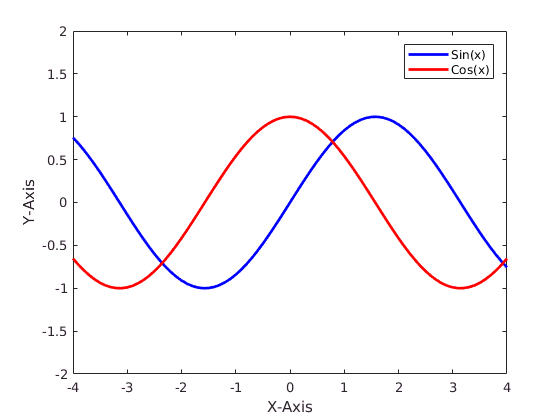

% what the hell is meshwidth?
x = -4:0.1:4;
c = cos(x);
s = sin(x);
p1 = plot(x,s, '-b'); hold on;
p2 = plot(x,c, '-r'); hold off;
p1.LineWidth = 2;
p2.LineWidth = 2;
legend('Sin(x)','Cos(x)');
xlabel('X-Axis');
ylabel('Y-Axis');
axis ( [-4 4 -2 2] )

Exercise 7

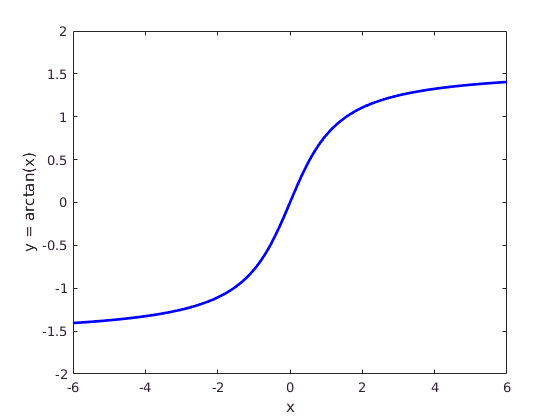

% get horizontal asymptopes. 
syms x1;
func = atan(x1);
asympt = limit(func,inf);
% get the graph
x = -6:0.1:6;
arct = atan(x);
p = plot(x,arct,'-b'); hold on;
as1 = plot(x,-asympt,'-r'); hold on;
as2 = plot(x,asympt,'-r'); hold off;
p.LineWidth = 2;
axis ( [-6 6 -2 2] );
xlabel('x');
ylabel('y = arctan(x)');

Exercise 8

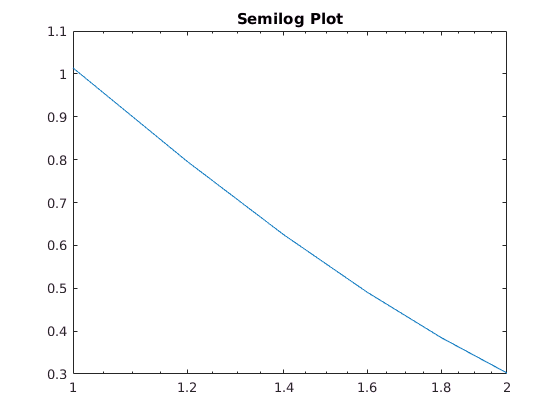

x = [1, 1.2, 1.4, 1.6, 1.8, 2];
y = [1.0139, 0.7959, 0.6249, 0.4906, 0.3851, 0.3023];

semilogx(x,y);
title('Semilog Plot');

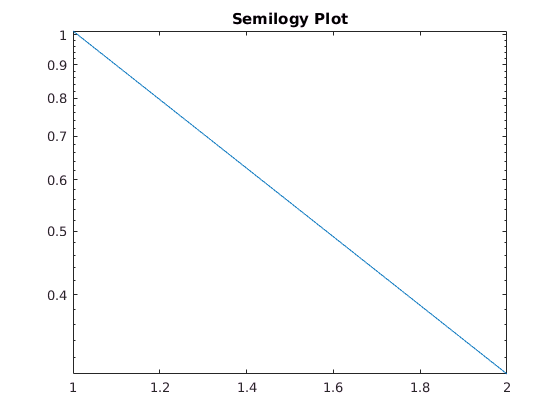

semilogy(x,y);
title('Semilogy Plot');

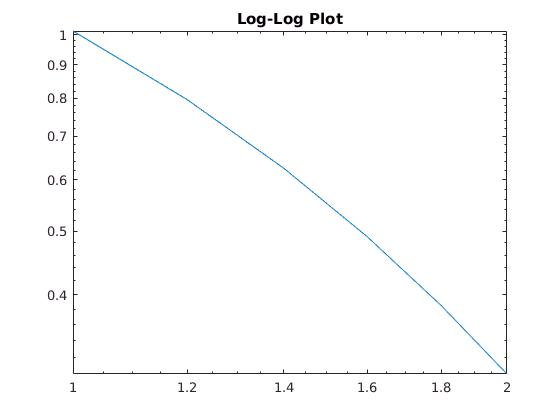

loglog(x,y);
title('Log-Log Plot');

This should show asymptopes but it does not

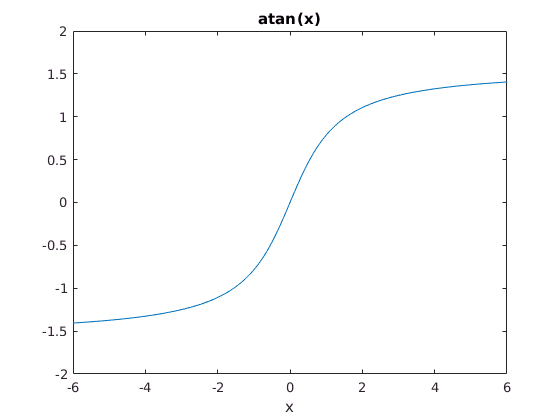

syms x;
f = atan(x);
fplot(f);
axis ( [-6 6 -2 2] );

MYSUM FUNCTION

function sum = mysum(n)
    sum = 0;
    for i = 1:n
        sum = sum + i;
    end
end

MYABSOLUTEVALUE FUNCTION

function out = myabsolutevalue(num)
    format longG;
    if(num >= 0)
        out = num;
    end
    if (num < 0)
        out = num * (-1);
    end
    disp(out)
end

VECTORNORM FUNCTION

function norm = vectornorm(x)
    sum = 0;
    for i = 1:size(x,2)
        sum = sum + ( x(i) * x(i));
    end
    norm = sqrt(sum);
end